# 21.1

1. 

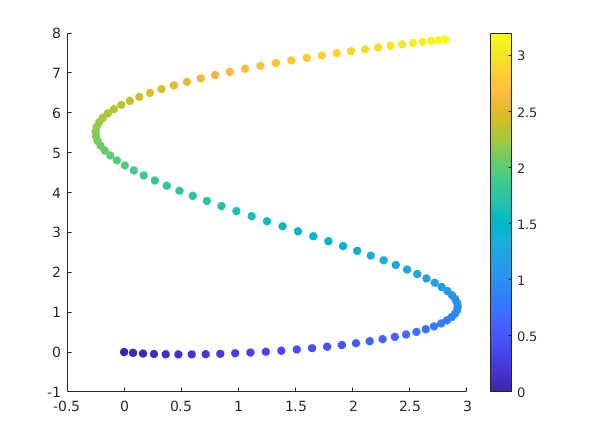

syms u
assume(u,["positive","real"])
r = 4 * [0.3960*cos(2.65 * (u + 1.4)); -0.99 * sin(u + 1.4); 0 * u];
r = simplify(r);

u_0 = 0;
u_max = 3.2;
u_num = linspace(u_0, u_max);
r_num = subs(r, u, u_num);
r_num(1,:) = r_num(1, :) - r_num(1,1);
r_num(2,:) = r_num(2, :) - r_num(2,1);

figure();
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar

2.

T_hat = simplify(diff(r,u)/norm(diff(r,u)));
N_hat = simplify(diff(T_hat,u)/norm(diff(T_hat,u)));
u_samples_indices = round(linspace(1, length(u_num), 5));
u_samples = u_num(u_samples_indices);
T_hat_samples = subs(T_hat, u, u_samples);
N_hat_samples = subs(N_hat, u, u_samples);

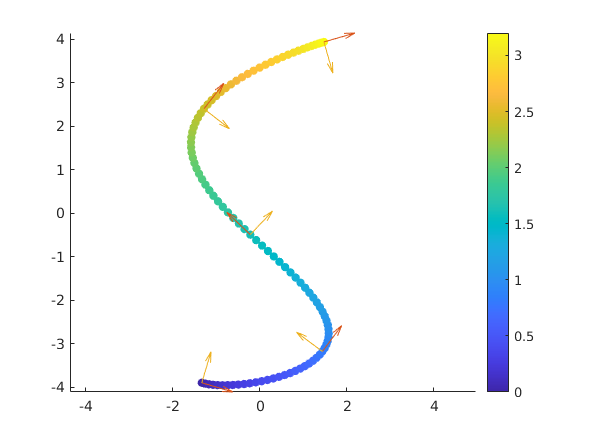

figure()
hold on
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), T_hat_samples(1,:), T_hat_samples(2,:), 0.2)
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), N_hat_samples(1,:), N_hat_samples(2,:), 0.2)
axis equal

# 21.2

1.

syms beta t
assume([beta, t], "real")
r_t = subs(r, u, beta * t)

$$r\_t = \left(\begin{array}{c} \frac{198\,\cos\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{125}\\ -\frac{99\,\sin\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

vel = diff(r_t, t)

$$vel = \left(\begin{array}{c} -\frac{5247\,\beta \,\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{1250}\\ -\frac{99\,\beta \,\cos\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

T_hat_t = subs(T_hat, u, beta*t);

vel_lin = dot(vel, T_hat_t)*T_hat_t;
vel_ang = cross(T_hat_t, diff(T_hat_t, t));

speed = norm(vel_lin);

sub_vals = struct();
sub_vals.beta = 0.5;
sub_vals.t = u_num/sub_vals.beta;

tspan = sub_vals.t;

speeds = subs(speed, sub_vals);
mat_omegas = eval(subs(vel_ang, sub_vals));
omegas = mat_omegas(3, :);

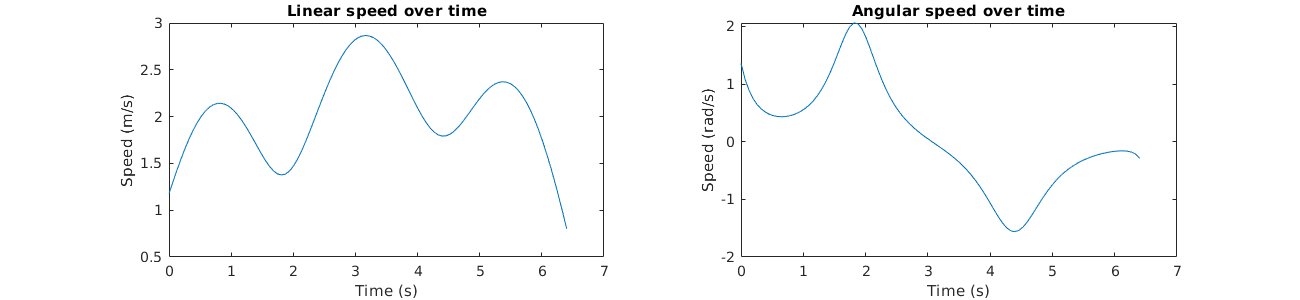

figure();
set(gcf, 'Position', [0, 0, 1300, 300])

subplot(1, 2, 1);
plot(tspan, speeds);
title("Linear speed over time")
xlabel("Time (s)")
ylabel("Speed (m/s)")

subplot(1, 2, 2);
plot(tspan, omegas);
title("Angular speed over time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")

# 21.3

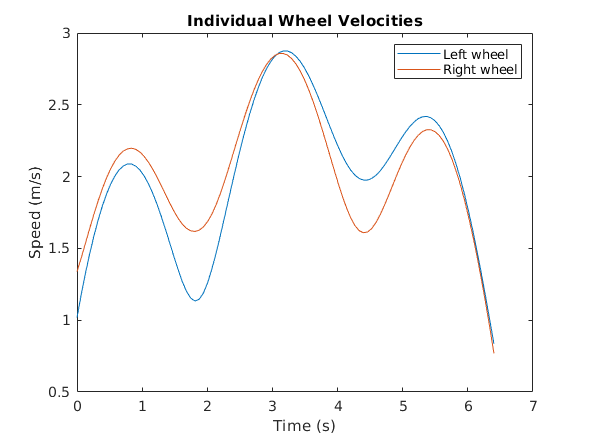

d = 0.235;
v_r = simplify(speed + vel_ang(3) * d / 2);
v_l = simplify(speed - vel_ang(3) * d / 2);

v_r_num = eval(subs(v_r,sub_vals));
v_l_num = eval(subs(v_l,sub_vals));
figure()
plot(tspan, v_l_num, tspan, v_r_num)
xlabel("Time (s)")
ylabel("Speed (m/s)")
legend("Left wheel", "Right wheel")
title("Individual Wheel Velocities")

# 21.4

starterCodeForBridgeOfDoomQEA2021();

%This line says we are going to publish to the topic `/raw_vel' 
%which are the left and right wheel velocities
pubvel = rospublisher('/raw_vel') 

pubvel =   Publisher with properties:

         TopicName: '/raw_vel'
        IsLatching: 1
    NumSubscribers: 1
       MessageType: 'std_msgs/Float32MultiArray'



%Here we are creating a ROS message
message = rosmessage(pubvel);  

%Set the right and left wheel velocities 
message.Data = [0, 0]; 

% Send the velocity commands to the NEATO
send(pubvel, message);

    
struct_current_vals = struct();
struct_current_vals.beta = 0.2;

% rostic allows us to do timing based on the simulator clock
elapsed = 0;
rostic;
while elapsed < 30
    % calculate the delta t from when we started moving using rostoc
    elapsed = rostoc;

    struct_current_vals.t = elapsed;
    v_l_current = eval(subs(v_l, struct_current_vals));
    v_r_current = eval(subs(v_r, struct_current_vals));
    
    message.Data = [v_l_current, v_r_current];
    send(pubvel, message); % send new wheel velocities
end

# 21.5

bod_02beta = readtable("bod_0.2beta.csv");

t_meas = bod_02beta.time_seconds_;
l_meas = bod_02beta.encoderLeft_meters_;
r_meas = bod_02beta.encoderRight_meters_;

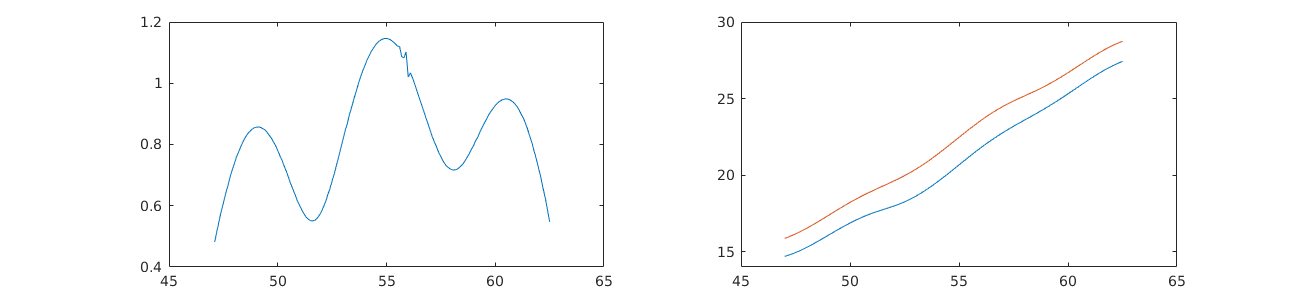

plot(t_meas, [l_meas(:)'; r_meas(:)'])

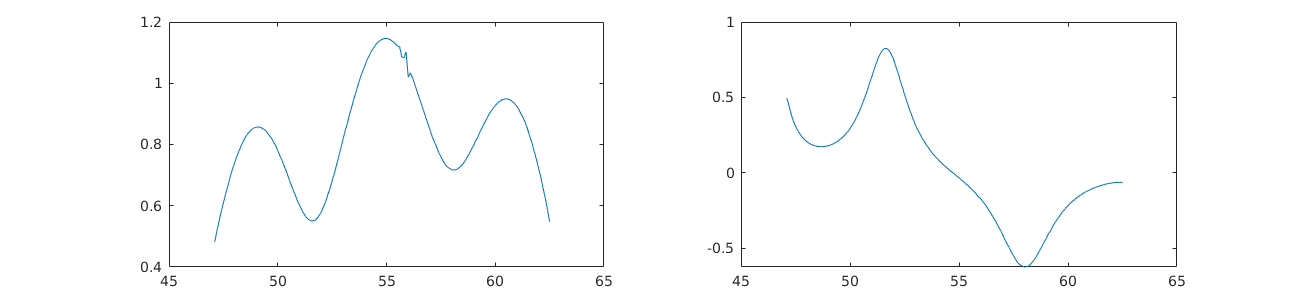

dt_meas = diff(t_meas);
v_l_meas = diff(l_meas) ./ dt_meas;
v_r_meas = diff(r_meas) ./ dt_meas;

speed_meas = (v_l_meas + v_r_meas) / 2;
omega_meas = (v_r_meas - v_l_meas) / d;

figure()
set(gcf, 'Position', [0, 0, 1300, 300]);

subplot(1, 2, 1)
plot(t_meas(2:end), speed_meas);

subplot(1, 2, 2)
plot(t_meas(2:end), omega_meas);

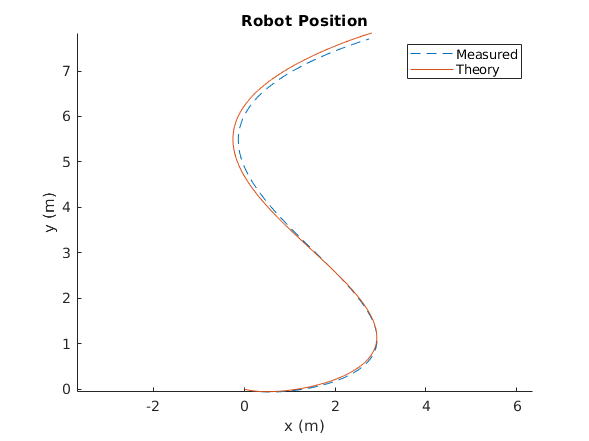

theta_0 = atan(eval(T_hat_samples(2,1)/T_hat_samples(1,1)));
thetas = cumtrapz(t_meas(2:end), omega_meas) + theta_0;

vel_meas = NaN(size(speed_meas,1), 2);

for i = 1:size(speed_meas,1)
    theta = thetas(i);
    vel_meas(i,:) = [cos(theta), -sin(theta); sin(theta), cos(theta)] * [speed_meas(i); 0];
end

pos_meas = cumtrapz(t_meas(2:end), vel_meas,1);
figure()
hold on
plot(pos_meas(:,1), pos_meas(:,2), "--")
plot(r_num(1, :), r_num(2, :))

axis equal
xlabel("x (m)")
ylabel("y (m)")
legend("Measured","Theory")
title("Robot Position")